% Get metadata from HDF4 file
hdfFile = "C:\Users\alam\Desktop\EOIRData\MOD11A2.A2022177.h09v06.061.2022186044223.hdf";
outputFile = "C:\Users\alam\Desktop\EOIRData\LSTOutput.csv";
hdfInfo = hdfinfo(hdfFile);

% Get CoreMetadata.0 for bounding lat/lon (GRingPointLongitude and
% GRingPointLatitude)
LSTInfo = hdfInfo.Attributes(5)

LSTInfo = struct with fields:
     Name: 'CoreMetadata.0'
    Value: '↵GROUP                  = INVENTORYMETADATA↵  GROUPTYPE            = MASTERGROUP↵↵  GROUP                  = ECSDATAGRANULE↵↵    OBJECT                 = LOCALGRANULEID↵      NUM_VAL              = 1↵      VALUE                = "MOD11A2.A2022177.h09v06.061.2022186044223.hdf"↵    END_OBJECT             = LOCALGRANULEID↵↵    OBJECT                 = PRODUCTIONDATETIME↵      NUM_VAL              = 1↵      VALUE                = "2022-07-05T04:42:23.000Z"↵    END_OBJECT             = PRODUCTIONDATETIME↵↵    OBJECT                 = DAYNIGHTFLAG↵      NUM_VAL              = 1↵      VALUE                = "Both"↵    END_OBJECT             = DAYNIGHTFLAG↵↵    OBJECT                 = REPROCESSINGACTUAL↵      NUM_VAL              = 1↵      VALUE                = "reprocessed"↵    END_OBJECT             = REPROCESSINGACTUAL↵↵    OBJECT                 = LOCALVERSIONID↵      NUM_VAL              = 1↵      VALUE               

% Display all datasets night-time LST specific metadata
struct2table(hdfInfo.Vgroup(1).Vgroup(1).SDS)

ans = 12×10 table
                                        Filename                                                 Type                      Name            Rank     DataType      Attributes          Dims          Label       Description    Index
    ________________________________________________________________________________    _______________________    ____________________    ____    __________    _____________    ____________    __________    ___________    _____

    {'C:\Users\alam\Desktop\EOIRData\MOD11A2.A2022177.h09v06.061.2022186044223.hdf'}    {'Scientific Data Set'}    {'LST_Day_1km'     }     2      {'uint16'}    {1×11 struct}    {2×1 

struct2table(hdfInfo.Vgroup(1).Vgroup(1).SDS(5).Attributes)

ans = 11×2 table
            Name                                    Value                        
    ____________________    _____________________________________________________

    {'long_name'       }    {'8-day nighttime 1km grid Land-surface Temperature'}
    {'units'           }    {'K'                                                }
    {'Number Type'     }    {'uint16'                                           }
    {'valid_range'     }    {[                                       7500 65535]}
    {'_FillValue'      }    {[                                                0]}
    {'LST'             }    {'LST data * scale_factor'                          }
    {'scale_factor'    }    {[                                           0.0200]}
    {'scale_factor_err'}    {[                                                0]}
    {'add_offset'      }    {[                                                0]}
    {'add_of

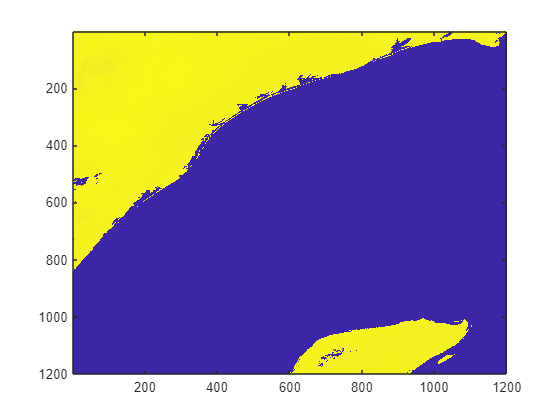

% Apply scale factor and display image
LSTdata = double(hdfread(hdfFile, 'LST_Night_1km')) * 0.02;
imagesc(LSTdata)

% Write to csv
writematrix(LSTdata, outputFile)